%This script use shooting method to find the optimal p
%Please run Vampire_plot before running this script

%Define parameters
h0 = 1;                 % Initial non-dimensional human population
v0 = h0 * 1 / 99;       % Initial non-dimensional vampire population
SIR_initial_ND = [h0; v0];

% Time step and total simulation time (non-dimensional time)
deltaT_ND = 0.001;          % Time step
tTotal_ND = 0.6;          % Total non-dimensional time

%Prepare for shooting method
% Threshold for minimum human population
h_min = 0.9;                % Desired minimum non-dimensional human population

p_tolerance = 1e-3;         % Tolerance for convergence
max_iterations = 1000;       % Maximum number of iterations

% Shooting Method to Find Optimal p
p_guess(1) = 0.05;
p_guess(2) = 0.1;
% Function to run the RK4 simulation and find the minimum human population
min_h = @(p_val) simulate_population(M, N, ds, p_val, SIR_initial_ND, deltaT_ND, tTotal_ND);

% Calculate the minimum human population for the initial guesses
[min_h1] = min_h(p_guess(1));
[min_h2] = min_h(p_guess(2));

% Calculate the error for the initial guesses
epsilon(1) = min_h1 - h_min;
epsilon(2) = min_h2 - h_min;



%Shooting
N_iter = 2;
while abs(epsilon(N_iter)) > p_tolerance && N_iter < max_iterations
    % Update the guess using the secant method
    p_guess(N_iter + 1) = p_guess(N_iter) - epsilon(N_iter) * (p_guess(N_iter) - p_guess(N_iter - 1)) / (epsilon(N_iter) - epsilon(N_iter - 1));
    
    % Calculate the new minimum human population for the updated guess
    min_h_new = min_h(p_guess(N_iter + 1));
    
    % Update the error
    epsilon(N_iter + 1) = min_h_new - h_min;
    
    % Display iteration details
    fprintf('Iteration %d: p = %.6f, min_h = %.6f, error = %.6f\n', N_iter, p_guess(N_iter + 1), min_h_new, epsilon(N_iter + 1));
    
    % Check if the error is within the tolerance
    if abs(epsilon(N_iter + 1)) < p_tolerance
        fprintf('Optimal regulation factor p_o found: %.6f\n', p_guess(N_iter + 1));
        break;
    end
    
    % Increment the iteration counter
    N_iter = N_iter + 1;
end

Iteration 2: p = 0.026950, min_h = 0.937111, error = 0.037111
Iteration 3: p = 0.035315, min_h = 0.888445, error = -0.011555
Iteration 4: p = 0.033329, min_h = 0.899856, error = -0.000144


Optimal regulation factor p_o found: 0.033329



% If the maximum iterations are reached without convergence
if (N_iter) > max_iterations
    fprintf('Failed to find an optimal p within %d iterations.\n', max_iterations);
end

% Display results
p_opt = p_guess(end)

p_opt = 0.0333

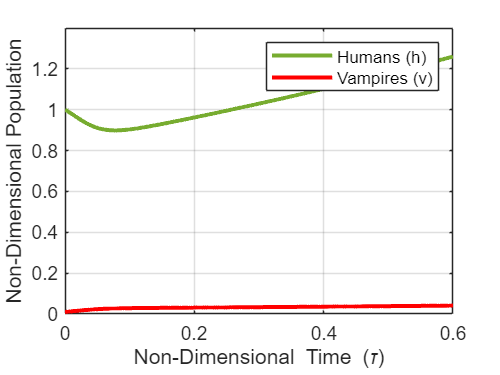


t_ND = zeros(1, tTotal_ND / deltaT_ND + 1);
t_ND(1) = 0; % Start with τ = 0
SIR_RK_ND = zeros(length(SIR_initial_ND), tTotal_ND / deltaT_ND + 1);
SIR_RK_ND(:, 1) = SIR_initial_ND;
n = 1;

while t_ND(n) <= tTotal_ND
    SIR_RK_ND(:, n + 1) = SIR_VAM_RK4_ND(deltaT_ND, SIR_RK_ND(:, n), M, N, O, p_opt);
    t_ND(n + 1) = t_ND(n) + deltaT_ND;
    n = n + 1;
end
% Plot the results with the optimal p
figure;
plot(t_ND, SIR_RK_ND(1, :), '-', 'Color', '#77AC30', 'LineWidth', 2); hold on;
plot(t_ND, SIR_RK_ND(2, :), '-', 'Color', '#FF0000', 'LineWidth', 2);
xlabel('Non-Dimensional Time (\tau)');
ylabel('Non-Dimensional Population');
legend('Humans (h)', 'Vampires (v)', 'Location', 'northeast');
%title(sprintf('Non-Dimensional Human-Vampire Dynamics with p = %.4f', p_opt));
grid on;
hold off;

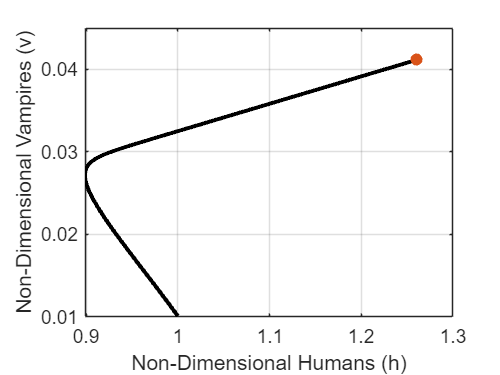


% Phase Plot: Humans vs Vampires
figure;
plot(SIR_RK_ND(1, :), SIR_RK_ND(2, :), 'k-', 'LineWidth', 2);
xlabel('Non-Dimensional Humans (h)');
ylabel('Non-Dimensional Vampires (v)');
%title('Phase Plot: Non-Dimensional Humans vs Vampires');
grid on;
hold on;
scatter(SIR_RK_ND(1, end), SIR_RK_ND(2, end), 'filled');
hold off;